# 2D Heat Flow in Circular Disk

clear, clc;

L = 300;
H = 300;
u = zeros(H, L);
xl = -1.5; xu = 1.5; yl = -1.5; yu = 1.5;
dx = (xu-xl)/L;
dy = (yu-yl)/H;

for x=1:L
    for y=1:H
        if ((x-L/2)*dx)^2 + ((y-H/2)*dy)^2 < 1
            if x <= L/2
                u(x,y) = -1;
            elseif x > L/2
                u(x,y) = 1;
            end
        end
    end
end

colormap("jet");

## Simulate

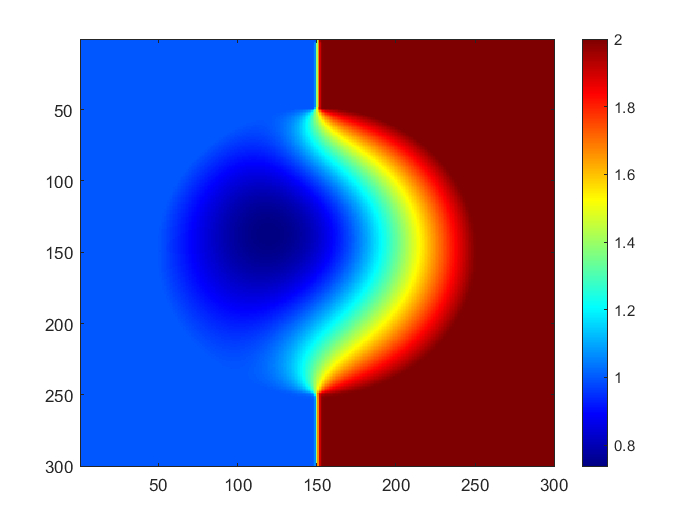

for t=1:3000
    if mod(t, 10) == 0
        imagesc(u);
        colorbar;
        drawnow;
    end
    
    for x=1:L
        for y=1:H
            if ((x-L/2)*dx)^2 + ((y-H/2)*dy)^2 > 1
                if y <= H/2
                    u(x,y) = 1;
                elseif y > H/2
                    u(x,y) = 2;
                end
            end
        end
    end
    
%     for x=1:L
%         for y=1:H
%             if ((x-L/2)*dx)^2 + ((y-H/2)*dy)^2 > 1
%                 u(x,y) = cos(atan2((y-H/2)*dy,(x-L/2)*dx));
%             end
%         end
%     end

%   By making laplace eqn true for each element
    for i=2:H-1
        for j=2:L-1
            u(i,j) = (u(i+1,j) + u(i+1,j+1) + u(i+1,j-1) + u(i-1,j) + u(i-1,j+1) + u(i-1,j-1) + u(i,j+1) + u(i,j-1)) / 8; % 8pt-Stencil
        end
    end
end